# Demonstration of PyColormap4Matlab

## Basic syntax

The syntax to retrieve the colormap values for a specific colormap, e.g. 'coolwarm', with 128 color quantization levels is

cmap = getPyPlot_cMap('coolwarm', 128);

In contrast to Matlab, colormaps in MatPlotLib also have an alpha channel, so there is a third arguments that allwos you to keep the alpha channel in the 4th column of the colormap:

cmap = getPyPlot_cMap('coolwarm', 128, true);
size(cmap)

ans =    128     4


If you need to specifiy the binary of your python interpreter (e.g. if your systen doesn't know the `python` command, or if you want to use a specific python version), you can pass the path to the binary as the 4th argument, e.g.:

cmap = getPyPlot_cMap('coolwarm', [], [], '"c:\Program Files\Python37\python.exe"');

Leaving the 2nd and 3rd argument empty uses the default values (128 and false respectively).

Note that you have to include the double quotes around the python-path if it contains space characters.

## Retrieve available colormap names

cmNames = getPyPlot_cMap('!GetNames');

This returns a cellstring containing all colormap names available in matplotlib. Lets print the colormap names:

fprintf([repmat('%-12s\t',1,5) '%-12s\n'],cmNames{:});

Accent      	Accent_r    	Blues       	Blues_r     	BrBG        	BrBG_r      
BuGn        	BuGn_r      	BuPu        	BuPu_r      	CMRmap      	CMRmap_r    
Dark2       	Dark2_r     	GnBu        	GnBu_r      	Greens      	Greens_r    
Greys       	Greys_r     	OrRd        	OrRd_r      	Oranges     	Oranges_r   
PRGn        	PRGn_r      	Paired      	Paired_r    	Pastel1     	Pastel1_r   
Pastel2     	Pastel2_r   	PiYG        	PiYG_r      	PuBu        	PuBuGn      
PuBuGn_r    	PuBu_r      	PuOr        	PuOr_r      	PuRd        	PuRd_r      
Purples     	Purples_r   	RdBu        	RdBu_r      	RdGy        	RdGy_r      
RdPu        	RdPu_r      	RdYlBu      	RdYlBu_r    	RdYlGn      	RdYlGn_r    
Reds        	Reds_r      	Set1        	Set1_r      	Set2        	Set2_r      
Set3        	Set3_r      	Spectral    	Spectral_r  	Wistia      	Wistia_r    
YlGn        	YlGnBu      	YlGnBu_r    	YlGn_r      	YlOrBr      	YlOrBr_r    
YlOrRd      	YlOrRd_r    	afmhot      	afmhot_r    	autumn      

## Visualize all colormaps

Retrieving all colormaps will take a while because the python script is called for each colormap.

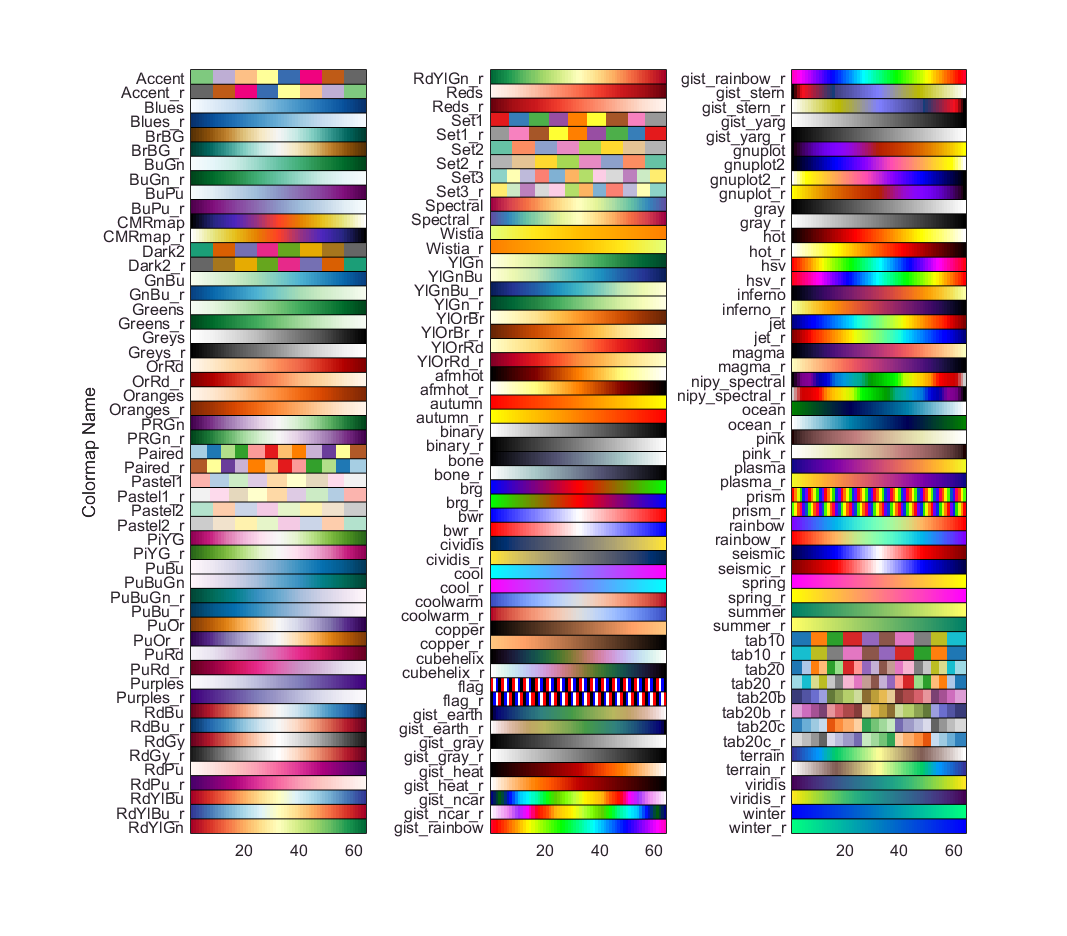

n_col = 64;
n_maps = numel(cmNames);
cmaps = zeros(n_maps,n_col,3);
for i=1:n_maps
    cmaps(i,:,:) = getPyPlot_cMap(cmNames{i},n_col);
end

nmap_split = round(n_maps .* [1/3 2/3]);
maps_SplitLimits = [0 nmap_split n_maps];
n_subsets = numel(nmap_split)+1;

for iMapSubset = n_subsets:-1:1
    mapsIdx = maps_SplitLimits(iMapSubset)+1:maps_SplitLimits(iMapSubset+1);
    n_mapSubset = numel(mapsIdx);
    
    axh = subplot(1,n_subsets,iMapSubset);
    image(axh, cmaps(mapsIdx,:,:));
    line(axh, [0 n_col+1], repmat((1.5:n_mapSubset).',1,2), ...
        'Color', 'k');
    set(axh, ...
        'FontSize',      12, ...
        'YLim',          [.5 n_mapSubset+.5], ...
        'YTick',         1:n_mapSubset, ...
        'YTickLabel',    strrep(cmNames(mapsIdx), '_', '\_'), ...
        'TickLength',    [0 0]);
end

axh.Parent.Units = 'points';
axh.Parent.Position = [0 0 800 max(diff(maps_SplitLimits))*13];

set(axh, 'YLabel', text('String','Colormap Name'));